clear all
close all

Leggo file audio

[data,Fs]=audioread('Audio/KDE_Startup.wav');

data=data(:,1)';

Dati

V = max(abs(data))

V = 1

nbit=6

nbit = 6

M=2^nbit

M = 64

DeltaV=2*V/M

DeltaV = 0.0313

pe=1e-5

pe = 1.0000e-05

Tc = 1/Fs

Tc = 4.5351e-05

B = 1/(2*Tc)

B = 11025


data_ = data*(1/V);

Partizzazione con Lloyd

partition=[-V+DeltaV:DeltaV:V-DeltaV];
codebook=[-V+DeltaV/2:DeltaV:V-DeltaV/2];
[l_partition, l_codebook] = lloyds(data_, codebook);

Quantizzazione

[l_index,l_quants]=quantiz(data_,l_partition,l_codebook);

l_word=de2bi(l_index,nbit);
l_word_out=bsc(l_word,pe);

Output ed errore

l_index_out=bi2de(l_word_out);
l_sig_out=l_codebook(l_index_out+1);
l_err=l_sig_out-data_;

Grafici

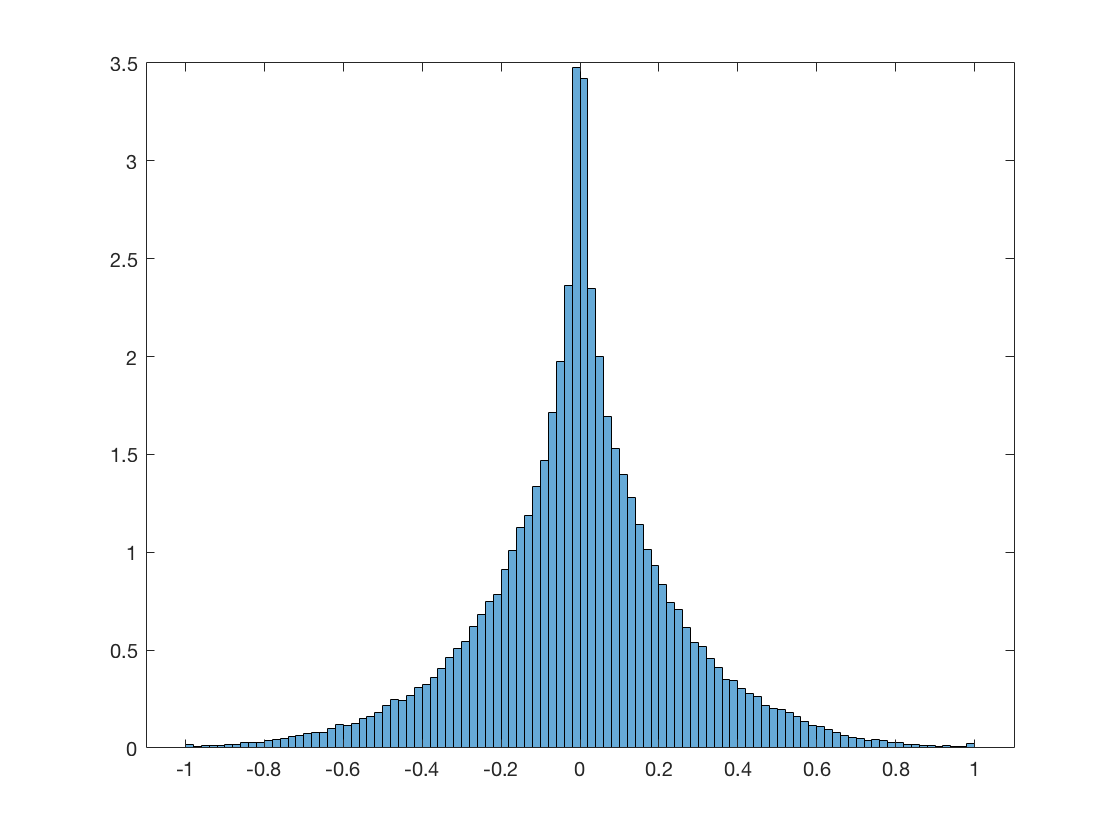

figure(1)
histogram(data_, 100, 'Normalization', 'pdf')

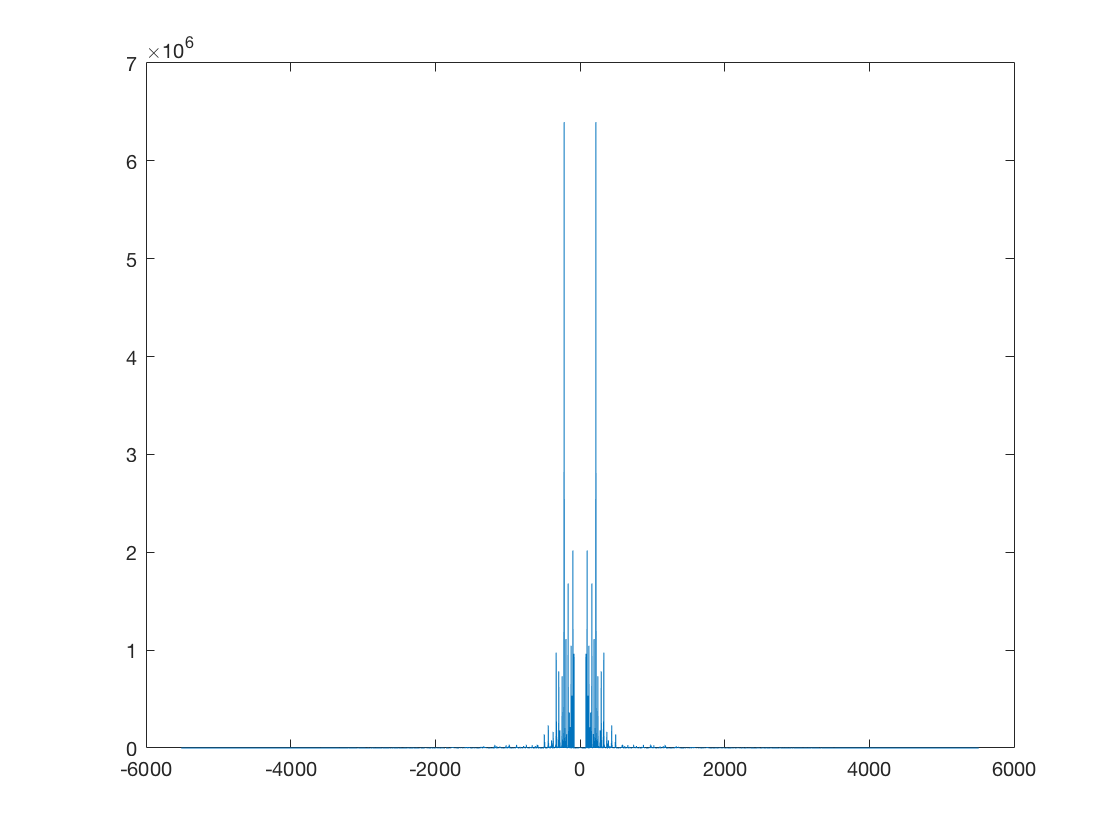


figure(2)
d_f = Fs/length(data_);
f = (-B/2):d_f:(B/2-d_f);
F = abs(fft(data_, length(f))).^2;

plot(f, fftshift(F))

Calcolo rapporto S/N teorico e pratico

N=var(l_err);
S=var(data_);

reale = 10*log10(S/N)

reale = 29.8190


teorico_pdf_gaussiana = 10*log10((3*M^2)/(V^2)*S)

teorico_pdf_gaussiana = 28.7513


teorico_pdf_uniforme = 10*log10(M^2)

teorico_pdf_uniforme = 36.1236